## Data Input 


%close all
clear all
colors=npg(10); % Ten basic colors 
maindir='\\Artemis-pc\e\Data\2024-01-11\Abs-401\';
main_dir_0=maindir;
load([maindir,'\population.mat']);
%load([maindir,'\173_Induced_171_Decoherence.mat']);


## Precession 

不同秒数下进动

默认s1 s2为173数据，s3 s4为171数据，s5为173归一化数据


%close all;

dual_Ramsey = 0;    % 是否画两种同位素
delete_odd = 0;    % 是否删除异常组
plot_all = 0;    % 是否画每一组进动曲线
average_plot = 0;   % 是否画平均后的点线图
vs_n_atom = 0;   % 是否画随单种同位素原子数变化曲线
decoherence_171_only = 0;   % 是否只观察171退相干

%x1 = [0.022:0.002:0.028 0.032:0.002:0.038];    % MOT Loading s
%x1 = 0.03:0.01:0.06
x1 = 0;
xlist = 10:5:100;

x_label = ['Precession ( ms )'];

y_lim_low = -1;
y_lim_high = 1;

x_lim_low = min(xlist);
x_lim_high = max(xlist);

relativeOD = (s1-s2)./(s1+s2);
repeat_se = length(relativeOD)/(length(x1)*length(xlist));
reshape_phase = reshape(relativeOD,length(xlist),repeat_se,length(x1));

n171 = n3+n4;
reshape_171 = reshape(n171,length(xlist),length(x1));
n173 = n1+n2;
reshape_173 = reshape(n173,length(xlist),length(x1));
n173_total = n5;
reshape_173_total = reshape(n173_total,length(xlist),length(x1));

s171 = s3+s4;
reshape_s_171 = reshape(s171,length(xlist),length(x1));
s173 = s1+s2;
reshape_s_173 = reshape(s173,length(xlist),length(x1));
s173_total = s5;
reshape_s_173_total = reshape(s173_total,length(xlist),length(x1));

if dual_Ramsey == 1 || decoherence_171_only == 1

    relativeOD2 = (s3-s4)./(s3+s4);
    repeat_se2 = length(relativeOD2)/(length(x1)*length(xlist));
    reshape_phase2 = reshape(relativeOD2,length(xlist),repeat_se2,length(x1));

end



if plot_all == 1
    for k = 1:length(x1)

        figure;hold on;
        for i = 1:repeat_se
            plot(xlist,reshape_phase(:,i,k),'*-');
            ylim([y_lim_low y_lim_high]);
        end
        legend('Location','best');
        hold off;

        if dual_Ramsey == 1 || decoherence_171_only == 1
            title(['Yb-173 ',num2str(x1(k)),'s']);

            figure;hold on;
            for i = 1:repeat_se2
                plot(xlist,reshape_phase2(:,i,k),'*-');
                ylim([y_lim_low y_lim_high]);
            end
            legend('Location','best');

            title(['Yb-171 ',num2str(x1(k)),'s']);

            hold off;

        end

    end
end


## Average


reduce_index = 0;  % 舍弃前几组

aver_phase = zeros(size(reshape_phase,1) , repeat_se-reduce_index , size(reshape_phase,3));
aver_phase = reshape_phase(:,(reduce_index+1):repeat_se,:);

phase_mean = mean(aver_phase,2);
phase_std = std(aver_phase,0,2);
phase_weight = 1./(phase_std).^2;

n171_mean = mean(reshape_171,1);
n171_std = std(reshape_171,0,1);
s171_mean = mean(reshape_s_171,1);
s171_std = std(reshape_s_171,0,1);

n173_mean = mean(reshape_173,1);
n173_std = std(reshape_173,0,1);
n173_var = var(reshape_173,0,1);
s173_mean = mean(reshape_s_173,1);
s173_std = std(reshape_s_173,0,1);
s173_var = var(reshape_s_173,0,1);

total173_mean = mean(reshape_173_total,1);
total173_std = std(reshape_173_total,0,1);
total173_var = var(reshape_173_total,0,1);
total_s_173_mean = mean(reshape_s_173_total,1);
total_s_173_std = std(reshape_s_173_total,0,1);
total_s_173_var = var(reshape_s_173_total,0,1);

if decoherence_171_only == 1
    n_ratio = total_s_173_mean./s171_mean;
elseif decoherence_171_only == 0
    n_ratio = s171_mean./total_s_173_mean;
end

cat_ratio = s173_mean./total_s_173_mean;
cat_var = s173_var./total_s_173_mean.^2 + total_s_173_var.*s173_mean.^2./total_s_173_mean.^4;
cat_std = sqrt(cat_var);


if dual_Ramsey == 1 || decoherence_171_only == 1

    reduce_index2 = 0;  % 舍弃前几组

    aver_phase2 = zeros(size(reshape_phase2,1) , repeat_se2-reduce_index2 , size(reshape_phase2,3));
    aver_phase2 = reshape_phase2(:,(reduce_index2+1):repeat_se2,:);

    phase_mean2 = mean(aver_phase2,2);
    phase_std2 = std(aver_phase2,0,2);
    phase_weight2 = 1./(phase_std2).^2;

end


## 排除异常组


if delete_odd == 1

    % 80s %
    temp_phase = aver_phase(:,:,6);
    temp_phase(:,1) = [];

    phase_mean(:,:,6) = mean(temp_phase,2);
    phase_std(:,:,6) = std(temp_phase,0,2);
    phase_weight2(:,:,6) = 1./(phase_std2(:,:,6)).^2;

    % 100s %
    temp_phase = aver_phase(:,:,7);
    temp_phase(:,2) = [];

    phase_mean(:,:,7) = mean(temp_phase,2);
    phase_std(:,:,7) = std(temp_phase,0,2);
    phase_weight2(:,:,7) = 1./(phase_std2(:,:,7)).^2;


    % Yb-171 %
    if dual_Ramsey == 1 || decoherence_171_only == 1

        % 60s %
        temp_phase2 = aver_phase2(:,:,5);
        temp_phase2(:,4) = [];
        temp_phase2(:,3) = [];
        temp_phase2(:,2) = [];

        phase_mean2(:,:,5) = mean(temp_phase2,2);
        phase_std2(:,:,5) = ones(size(temp_phase2,1),1);
        phase_weight2(:,:,5) = 1./(phase_std2(:,:,5)).^2;

        % 80s %
        temp_phase2 = aver_phase2(:,:,6);
        temp_phase2(:,1) = [];

        phase_mean2(:,:,6) = mean(temp_phase2,2);
        phase_std2(:,:,6) = std(temp_phase2,0,2);
        phase_weight2(:,:,6) = 1./(phase_std2(:,:,6)).^2;

        % 100s %
        temp_phase = aver_phase(:,:,7);
        temp_phase(:,3) = [];

        phase_mean(:,:,7) = mean(temp_phase,2);
        phase_std(:,:,7) = std(temp_phase,0,2);
        phase_weight2(:,:,7) = 1./(phase_std2(:,:,7)).^2;

    end

end


## Average Plot


if average_plot == 1
    if dual_Ramsey == 0 && decoherence_171_only == 0

        for k = 1:length(x1)

            figure;
            I_se = errorbar(xlist,phase_mean(:,k),1.*phase_std(:,k)./sqrt(repeat_se-1),'o-');


            xlabel(x_label);
            %ylabel('OD 2/OD 1');
            %ylabel('OD 2');
            ylabel('S_z');
            title([num2str(x1(k)),'s']);

            set(gca,'FontSize',18);
            xlim([x_lim_low x_lim_high]);
            ylim([y_lim_low y_lim_high]);

            I_se.CapSize = 0;
            I_se.MarkerSize = 50;
            I_se.LineWidth = 2;
            I_se.Color = [0.5,0.4,0.3];
            I_se.MarkerSize = 6;
            I_se.MarkerEdgeColor = [0.7 0 0];
            I_se.MarkerFaceColor = [1 0.6 0.5];

        end

    end

    if dual_Ramsey == 1 || decoherence_171_only == 1

        for k = 1:length(x1)

            figure;hold on;
            I_se1 = errorbar(xlist,phase_mean(:,k),phase_std(:,k)./sqrt(repeat_se-1),'o-');
            I_se2 = errorbar(xlist,phase_mean2(:,k),phase_std2(:,k)./sqrt(repeat_se2-1),'o-');


            xlabel(x_label);
            ylabel('S_z');
            title([num2str(x1(k)),'s']);
            legend('Yb-173','Yb-171','Location','best')

            set(gca,'FontSize',18);
            xlim([x_lim_low x_lim_high]);
            ylim([y_lim_low y_lim_high]);

            I_se1.CapSize=0;
            I_se1.MarkerSize=50;
            I_se1.LineWidth=2;
            I_se1.Color=[0.45,0.63,0.67];
            I_se1.MarkerSize=6;
            I_se1.MarkerEdgeColor=[0.04,0.59,0.83];
            I_se1.MarkerFaceColor=[0.29,0.91,0.91];

            I_se2.CapSize = 0;
            I_se2.MarkerSize = 50;
            I_se2.LineWidth = 2;
            I_se2.Color = [0.5,0.4,0.3];
            I_se2.MarkerSize = 6;
            I_se2.MarkerEdgeColor = [0.7 0 0];
            I_se2.MarkerFaceColor = [1 0.6 0.5];

            hold off;

        end

    end
end


## Fit

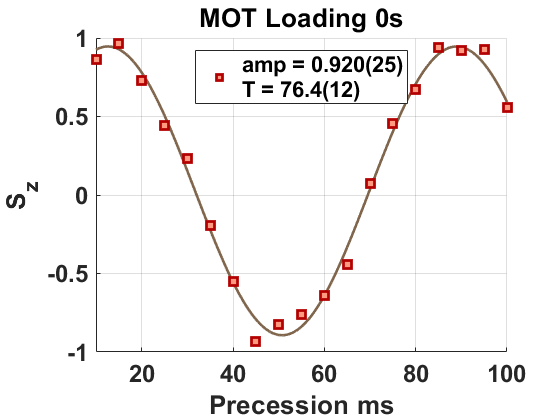


for k = 1:length(x1)

    if repeat_se == 1
        [xData, yData] = prepareCurveData(xlist,phase_mean(:,:,k));
    else
        [xData, yData, weight] = prepareCurveData(xlist,phase_mean(:,:,k),phase_weight(:,:,k));
    end

    % 设置 fittype 和选项。
    ft = fittype( 'a*sin(2*pi*x/T+b)+c', 'independent', 'x', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.Lower = [40 0.1 -2*pi -5];
    opts.Upper = [130 1.5 2*pi 5];
    opts.StartPoint = [80 0.8 0.9 0.9];

    % 对数据进行模型拟合。
    [fitresult, gof] = fit(xData, yData, ft, opts);
    amp(k) = fitresult.a;
    T(k) = fitresult.T;
    interval = confint(fitresult);
    a_sigma(k) = (interval(2,2)-interval(1,2))/4;
    T_sigma(k) = (interval(2,1)-interval(1,1))/4;


    if dual_Ramsey == 0 && decoherence_171_only == 0

        % 绘制数据拟合图。
        h1(k) = figure;hold on;
        l = plot(fitresult, xData, yData);
        I = errorbar(xData,yData,phase_std(:,:,k)./sqrt(repeat_se-1),'square',MarkerSize=8);

        l(1).Marker = 'square';
        l(1).MarkerSize = 6;
        l(1).MarkerEdgeColor = [0.7 0 0];
        l(1).MarkerFaceColor = [1 0.6 0.5];
        l(2).Color = [0.5,0.4,0.3];
        l(2).LineWidth = 2;

        I.MarkerEdgeColor = [0.7 0 0];
        I.MarkerFaceColor = [1 0.6 0.5];
        I.CapSize = 0;
        I.Color = [0.5 0.4 0.3];
        I.LineWidth = 2;

        xlabel( 'Precession ms' );
        ylabel( 'S_z' );

        set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
            'child',[I,l(1),l(2)]);
        legend('','',['amp = ',num2str(roundn(amp(k),-3),'%.3f'),'(',num2str(round(a_sigma(k)*1000)),')',...
            newline 'T = ',num2str(roundn(T(k),-1),'%.1f'),'(',num2str(round(T_sigma(k)*10)),')'],...
            'Location','best');
        grid on;
        xlim([x_lim_low,x_lim_high]);
        ylim([y_lim_low,y_lim_high]);
        title(['MOT Loading ',num2str(x1(k)),'s'],'FontName','Arial','FontWeight','bold');

        hold off;

        set(gcf,'Visible','on');

        savefig(h1(k),[main_dir_0,'\Fit_',num2str(x1(k)),'s_',num2str(k),'.fig']);
        saveas(h1(k),[main_dir_0,'\Fit_',num2str(x1(k)),'s_',num2str(k),'.png']);

    end


    if dual_Ramsey == 1 || decoherence_171_only == 1

        if repeat_se2 == 1
            [xData2, yData2] = prepareCurveData(xlist,phase_mean2(:,:,k));
        else
            [xData2, yData2, weight2] = prepareCurveData(xlist,phase_mean2(:,:,k),phase_weight2(:,:,k));
        end

        % 设置 fittype 和选项。
        ft2 = fittype( 'a*sin(2*pi*x/T+b)+c', 'independent', 'x', 'dependent', 'y' );
        opts2 = fitoptions( 'Method', 'NonlinearLeastSquares' );
        opts2.Display = 'Off';
        opts2.Lower = [60 0.2 -2*pi -5];
        opts2.Upper = [150 1.5 2*pi 5];
        opts2.StartPoint = [108 0.9 0.9 0.9];

        % 对数据进行模型拟合。
        [fitresult2, gof2] = fit(xData2, yData2, ft2, opts2);
        amp2(k) = fitresult2.a;
        T2(k) = fitresult2.T;
        interval2 = confint(fitresult2);
        a_sigma2(k) = (interval2(2,2)-interval2(1,2))/4;
        T_sigma2(k) = (interval2(2,1)-interval2(1,1))/4;


        % 绘制数据拟合图。
        h2(k) = figure;hold on;
        l1 = plot(fitresult, xData, yData);
        I1 = errorbar(xData,yData,phase_std(:,:,k)./sqrt(repeat_se-1),'square',MarkerSize=8);

        l2 = plot(fitresult2, xData2, yData2);
        I2 = errorbar(xData2,yData2,phase_std2(:,:,k)./sqrt(repeat_se2-1),'square',MarkerSize=8);

        l1(1).Marker = 'square';
        l1(1).MarkerSize = 6;
        l1(2).Color = [0.45 0.63 0.67];
        l1(2).LineWidth = 2;
        
        I1.MarkerEdgeColor = [0.04 0.59 0.83];
        I1.MarkerFaceColor = [0.29 0.91 0.91];
        I1.CapSize = 0;
        I1.LineWidth = 2;
        I1.Color = [0.45 0.63 0.67];

        l2(1).Marker = 'square';
        l2(1).MarkerSize = 6;
        l2(2).Color = [0.5 0.4 0.3];
        l2(2).LineWidth = 2;

        I2.MarkerEdgeColor = [0.7 0 0];
        I2.MarkerFaceColor = [1 0.6 0.5];
        I2.CapSize = 0;
        I2.Color = [0.5 0.4 0.3];
        I2.LineWidth = 2;

        xlabel( 'Precession ms' );
        ylabel( 'S_z' );
        title(['Precession ',num2str(x1(k)),'s'],'FontName','Arial','FontWeight','bold');
        set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
            'child',[I1,l1(1),l1(2),I2,l2(1),l2(2)]);
        legend('','',['amp-171 = ',num2str(roundn(amp2(k),-3),'%.3f'),'(',num2str(round(a_sigma2(k)*1000)),')'],...
            '','',['amp-173 = ',num2str(roundn(amp(k),-3),'%.3f'),'(',num2str(round(a_sigma(k)*1000)),')'],...
            'Location','best');
        grid on;
        xlim([x_lim_low,x_lim_high]);
        ylim([y_lim_low,y_lim_high]);

        hold off;

        set(gcf,'Visible','on');

        savefig(h2(k),[main_dir_0,'\Fit_',num2str(x1(k)),'s.fig']);
        saveas(h2(k),[main_dir_0,'\Fit_',num2str(x1(k)),'s.png']);

    end

end

## Contrast

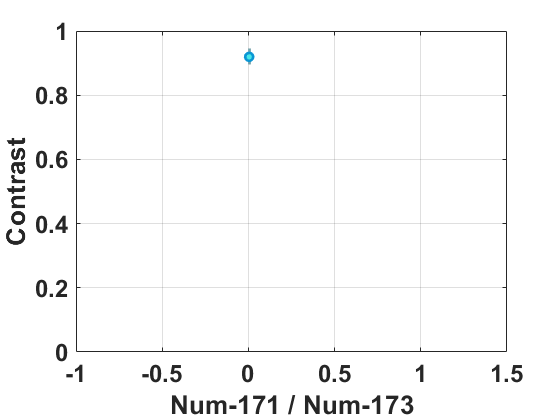


if vs_n_atom == 1

    % Contrast v.s. Yb-171 %
    a_weight = 1./a_sigma.^2;

    h3 = figure;

    if decoherence_171_only == 0   % 173 Contrast

        li = errorbar(n171_mean,amp,a_sigma,'o', LineWidth=2, MarkerSize=6);

        li.CapSize = 0;
        li.MarkerEdgeColor = [0.04,0.59,0.83];
        li.MarkerFaceColor = [0.29,0.91,0.91];
        li.Color = [0.45,0.63,0.67];

    end

    if dual_Ramsey == 1 || decoherence_171_only == 1   % 171 Contrast

        a_weight2 = 1./a_sigma2.^2;

        hold on;
        li2 = errorbar(n171_mean,amp2,a_sigma2,'o', LineWidth=2, MarkerSize=6)

        li2.CapSize = 0;
        li2.MarkerEdgeColor = [0.7 0 0];
        li2.MarkerFaceColor = [1 0.6 0.5];
        li2.Color = [0.5 0.4 0.3];

        if dual_Ramsey == 1 && decoherence_171_only == 0
            legend('Yb-173','Yb-171','Location','best');
        end

    end

    xlabel('Num of Yb-171');
    ylabel('Contrast');
    set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
        'YScale','linear','XScale','linear');
    ylim([0 1]);
    xlim([min(n171_mean) max(n171_mean)]);
    grid on;

    set(gcf,'Visible','on');

    savefig(h3,[main_dir_0,'Contrast_vs_n171.fig']);
    saveas(h3,[main_dir_0,'Contrast_vs_n171.png']);


    % Contrast v.s. Yb-173 %
    h4 = figure;

    if decoherence_171_only == 0   % 173 Contrast

        li3 = errorbar(total173_mean,amp,a_sigma,'o', LineWidth=2, MarkerSize=6);

        li3.CapSize = 0;
        li3.MarkerEdgeColor = [0.04,0.59,0.83];
        li3.MarkerFaceColor = [0.29,0.91,0.91];
        li3.Color = [0.45,0.63,0.67];

    end

    if dual_Ramsey == 1 || decoherence_171_only == 1   % 171 Contrast

        a_weight2 = 1./a_sigma2.^2;

        hold on;
        li4 = errorbar(total173_mean,amp2,a_sigma2,'o', LineWidth=2, MarkerSize=6)

        li4.CapSize = 0;
        li4.MarkerEdgeColor = [0.7 0 0];
        li4.MarkerFaceColor = [1 0.6 0.5];
        li4.Color = [0.5 0.4 0.3];

        if dual_Ramsey == 1 && decoherence_171_only == 0
            legend('Yb-173','Yb-171','Location','best');
        end

    end

    xlabel('Num of Yb-173');
    ylabel('Contrast');
    set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
        'YScale','linear','XScale','linear');
    ylim([0 1]);
    xlim([min(total173_mean) max(total173_mean)]);
    grid on;

    set(gcf,'Visible','on');

    savefig(h4,[main_dir_0,'Contrast_vs_n173.fig']);
    saveas(h4,[main_dir_0,'Contrast_vs_n173.png']);

end


% Contrast v.s. Num Ratio %
h5 = figure;

if decoherence_171_only == 0

    li5 = errorbar(n_ratio,amp,a_sigma,'o', LineWidth=2, MarkerSize=6);

    li5.CapSize = 0;
    li5.MarkerEdgeColor = [0.04,0.59,0.83];
    li5.MarkerFaceColor = [0.29,0.91,0.91];
    li5.Color = [0.45,0.63,0.67];

    xlabel('Num-171 / Num-173');

end

if dual_Ramsey == 1 || decoherence_171_only == 1

    hold on;
    li6 = errorbar(n_ratio,amp2,a_sigma2,'o', LineWidth=2, MarkerSize=6);

    li6.CapSize = 0;
    li6.MarkerEdgeColor = [0.7 0 0];
    li6.MarkerFaceColor = [1 0.6 0.5];
    li6.Color = [0.5 0.4 0.3];

    if decoherence_171_only == 1
        xlabel('Num-173 / Num-171');
    elseif dual_Ramsey == 1 && decoherence_171_only == 0
        legend('Yb-173','Yb-171','Location','best');
    end

end

ylabel('Contrast');
set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
    'YScale','linear','XScale','linear');
ylim([0 1]);
grid on;

set(gcf,'Visible','on');


if length(x1) > 1

    xlim([0 max(n_ratio)]);

    savefig(h5,[main_dir_0,'Contrast_vs_ratio.fig']);
    saveas(h5,[main_dir_0,'Contrast_vs_ratio.png']);

end


## Cat Ratio

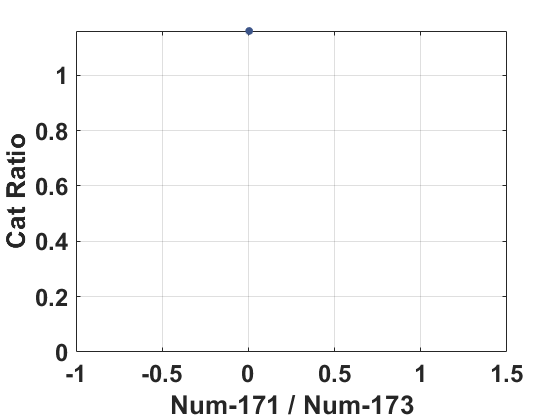


if decoherence_171_only == 0

    if vs_n_atom == 1

        % Cat Ratio v.s. Yb-171 %
        h6 = figure;

        I_cat1 = plot(n171_mean,cat_ratio,...
            '.','Color',colors(1,:),'LineWidth',1.8,'MarkerSize',20);

        xlabel('Num of Yb-171');
        ylabel('Cat Ratio');
        set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
            'YScale','linear','XScale','linear');
        ylim([0 max(max(cat_ratio),1)]);
        xlim([min(n171_mean) max(n171_mean)]);
        grid on;

        set(gcf,'Visible','on');

        savefig(h5,[main_dir_0,'cat_vs_n171.fig']);
        saveas(h5,[main_dir_0,'cat_vs_n171.png']);


        % Cat Ratio v.s. Yb-173 %
        h6 = figure;

        I_cat2 = plot(total173_mean,cat_ratio,...
            '.','Color',colors(2,:),'LineWidth',1.8,'MarkerSize',20);

        xlabel('Num of Yb-173');
        ylabel('Cat Ratio');
        set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
            'YScale','linear','XScale','linear');
        ylim([0 max(max(cat_ratio),1)]);
        xlim([min(total173_mean) max(total173_mean)]);
        grid on;

        set(gcf,'Visible','on');

        savefig(h6,[main_dir_0,'cat_vs_n173.fig']);
        saveas(h6,[main_dir_0,'cat_vs_n173.png']);

    end


    % Cat Ratio v.s. Num Ratio %
    h8 = figure;

    I_cat3 = plot(n_ratio,cat_ratio,...
        '.','Color',colors(4,:),'LineWidth',1.8,'MarkerSize',20);

    xlabel('Num-171 / Num-173');
    ylabel('Cat Ratio');
    set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
        'YScale','linear','XScale','linear');
    ylim([0 max(max(cat_ratio),1)]);
    grid on;

    set(gcf,'Visible','on');

    if length(x1) > 1

        xlim([0 max(n_ratio)]);

        savefig(h8,[main_dir_0,'cat_vs_ratio.fig']);
        saveas(h8,[main_dir_0,'cat_vs_ratio.png']);

    end

end


if decoherence_171_only == 1
    save([main_dir_0,'\173_Induced_171_Decoherence.mat']);
else
    save([main_dir_0,'\171_Induced_173_Decoherence.mat']);
end